clear all
d=load('reto4.mat');
tiempo=length(d.t);
data=zeros(tiempo,3);
data(:,1)=d.S;
data(:,2)=d.I;
data(:,3)=d.R;
t=zeros(1,tiempo);
t(1,:)=d.t;


% Datos de ejemplo (serie temporal)
datos = data;
% Longitud de la ventana de la media móvil
ventana = 50;

% Calcular la media móvil simple (SMA)
sma = movmean(datos, ventana);

% Mostrar los resultados
disp('Datos originales:');

Datos originales:


disp(datos);

        1228           2           0
        1228           2           0
        1228           2           0
        1228           2           0
        1228           2           0
        1227           3           0
        1228           1           1
        1228           2           0
        1228           2           0
        1228           2           0
        1228           2           0
        1228           2           0
        1228           2           0
        1228           2           0
        1227           3           0
        1228           2           0
        1227           3           0
        1228           2           0
        1228           2           0
        1228           2           0
        1227           3           0
        1226           4           0
        1227           3           0
        1228           2           0
        1228           2           0
        1227           3           0
        1226           4           0
 

disp(['Media Móvil Simple (SMA) con ventana de ', num2str(ventana), ':']);

Media Móvil Simple (SMA) con ventana de 50:


disp(sma);

   1.0e+03 *

    1.2277    0.0022    0.0000
    1.2277    0.0023    0.0000
    1.2276    0.0023    0.0000
    1.2276    0.0024    0.0000
    1.2276    0.0024    0.0000
    1.2276    0.0024    0.0000
    1.2276    0.0024    0.0000
    1.2276    0.0024    0.0000
    1.2276    0.0024    0.0000
    1.2276    0.0024    0.0000
    1.2276    0.0024    0.0000
    1.2276    0.0024    0.0000
    1.2276    0.0024    0.0000
    1.2276    0.0024    0.0000
    1.2275    0.0025    0.0000
    1.2275    0.0025    0.0000
    1.2275    0.0025    0.0000
    1.2275    0.0025    0.0000
    1.2274    0.0025    0.0000
    1.2274    0.0025    0.0000
    1.2274    0.0026    0.0000
    1.2273    0.0027    0.0000
    1.2273    0.0026    0.0000
    1.2273    0.0027    0.0000
    1.2273    0.0027    0.0000
    1.2273    0.0027    0.0000
    1.2273    0.0027    0.0000
    1.2272    0.0027    0.0000
    1.2272    0.0027    0.0000
    1.2272    0.0027    0.0000
    1.2272    0.0028    0.0000
    1.2271    0.0028    0

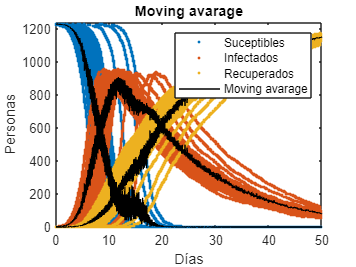


plot(t,datos,'.')
hold on
plot(t,sma,'black')
title('Moving avarage');
xlim([0 50]);
ylim([0 1240]);
xlabel('Días');
ylabel('Personas');
legend('Suceptibles','Infectados','Recuperados','Moving avarage');